# SCEC FIGURES:

## Global variable

focalMechanismArray = {'strike slip','normal','reverse'};
maxDepth            = 55; %km
colors              = {[0         0.4470    0.7410]; ...
                       [0.4660    0.6740    0.1880]; ...
                       [0.7350    0.0880    0.2840]}; % set this
depthRange          = [0,maxDepth];
fnArray = {'/auto/home/kdascher/Documents/UCSC/general_data/Earthquake_data/SCEDC/SCEDC_CAT_all_AB.mat',...
           'eq_catalog.mat'};
globalFileName = fnArray{2};
co = [0         0.4470    0.7410; ...
      0.4660    0.6740    0.1880; ...
      0.7350    0.0880    0.2840]; % set the color order 
set(groot,'defaultAxesColorOrder',co)

aftershock_productivity_kernel(globalFileName, ...
            'DepthRange',depthRange, ...
            'PlotYN', 'no');
        
load mainshock_info.mat
MSback = get_background_rate;

## Context

This is the motivation of the project which follows the findings from

Bootstrap resample

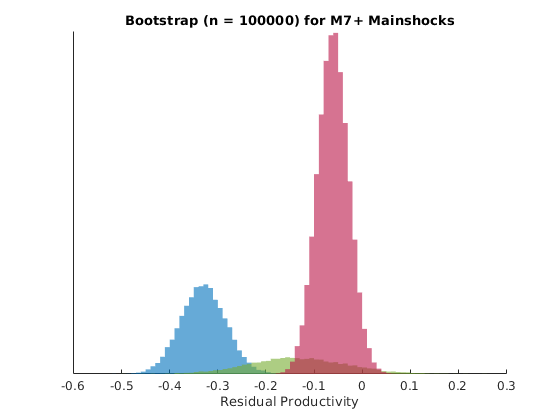


bootstrapHist()

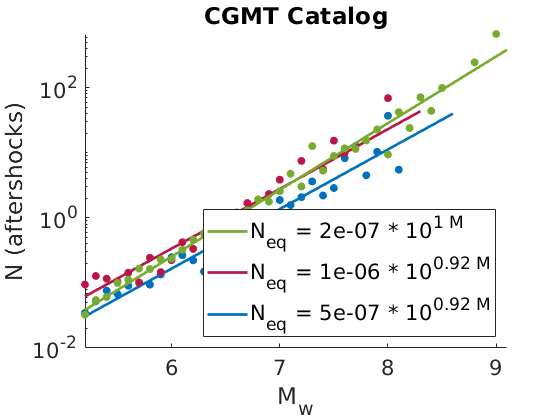


figure; hold on;

for n = 1:3    
    aftershock_productivity_kernel(globalFileName, ...
        'DepthRange',depthRange, ...
        'FocalMechanism', focalMechanismArray{n});
end
hLegend = findobj(gcf, 'Type', 'Legend');
%get text
Str = hLegend.String;
hLines = findobj(gcf, 'Type', 'Line');
legend('off');
legend(hLines, {hLines.DisplayName}, 'Location','southeast');
xlim([5.2 9.1])
title('CGMT Catalog')
ylabel('N (aftershocks)')
xlabel('M_w')
set(findall(gcf,'-property','FontSize'),'FontSize',16)
grid off

## Plate boundary

This explores whether the the tectonic setting affects the productivity of earthquakes

Starting parallel pool (parpool) using the 'local' profile ...
connected to 6 workers.


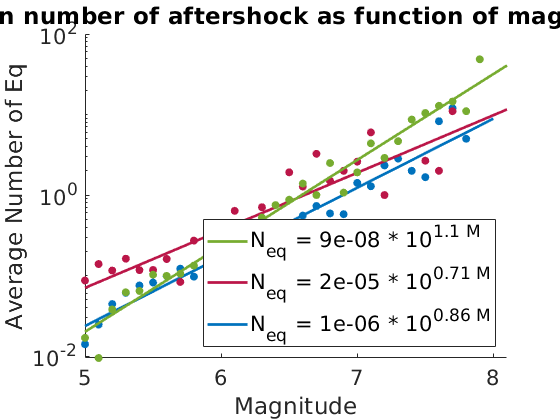

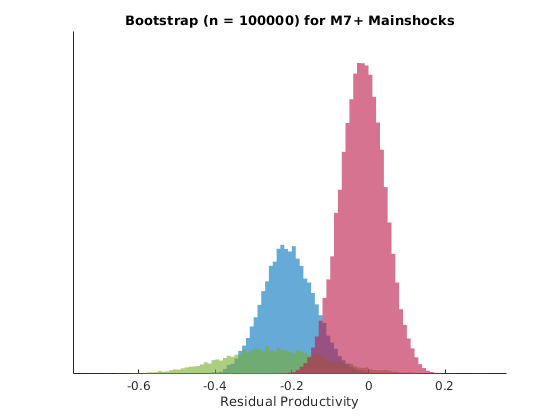

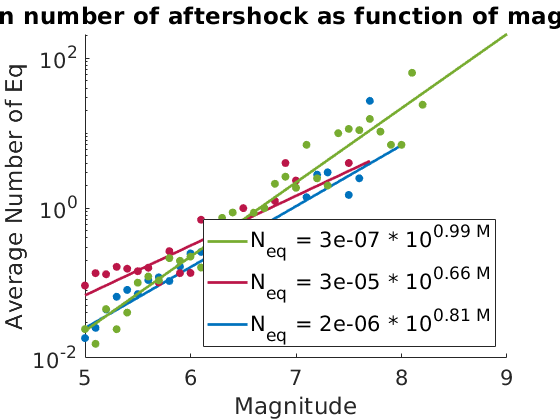

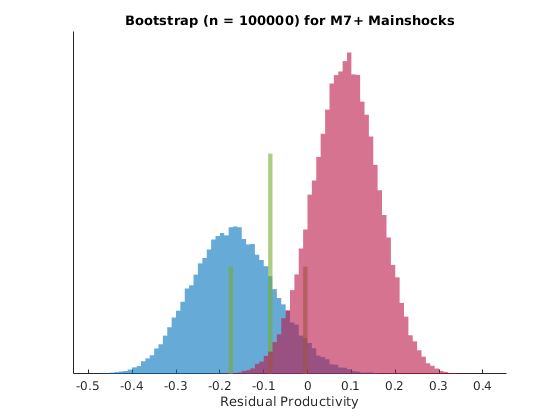

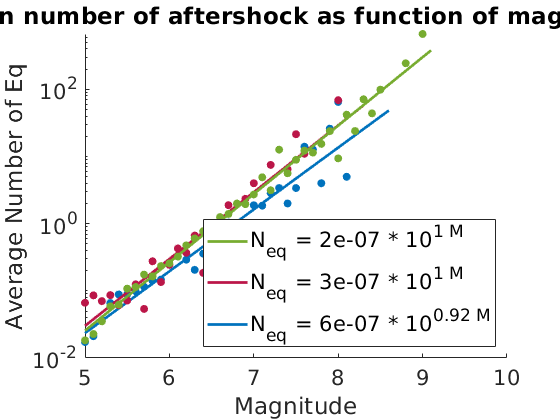

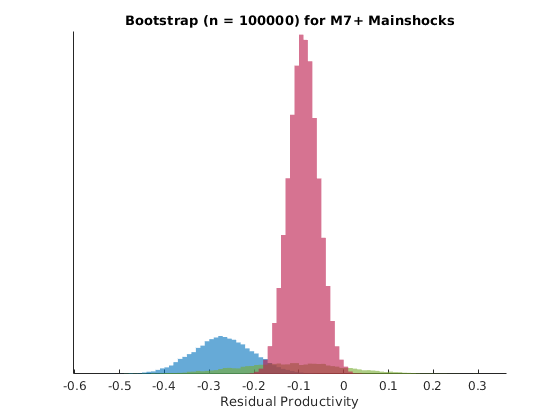

plateBoundaryDist = [100, 200,400];
plateBoundaries   = {'transform', 'divergent','convergent'};

for m =1:length(plateBoundaries)
    figure; hold on;
    for n = 1:length(focalMechanismArray)
        aftershock_productivity_kernel(globalFileName, ...
            'DepthRange',           depthRange, ...
            'FocalMechanism',       focalMechanismArray{n}, ...
            'PlateBoundary',        plateBoundaries{m}, ...
            'PlateBoundaryDist',    plateBoundaryDist(m));
    end
    hLegend = findobj(gcf, 'Type', 'Legend');
    %get text
    Str = hLegend.String;
    hLines = findobj(gcf, 'Type', 'Line');
    legend('off');
    legend(hLines, {hLines.DisplayName}, 'Location','southeast');
    grid off
    set(findall(gcf,'-property','FontSize'),'FontSize',16)
    
    aftershock_productivity_kernel(globalFileName, ...
            'DepthRange',           depthRange, ...
            'PlateBoundary',        plateBoundaries{m}, ...
            'PlateBoundaryDist',    plateBoundaryDist(m), ...
            'PlotYN',               'no');
    bootstrapHist()    
end

## Background Seismicity

Look at the relationship between 

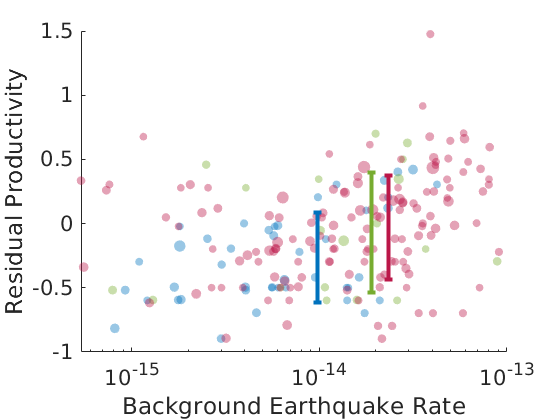

figure; hold on;

for n = 1:3
    I = MSfms ==n     & ...
        ~isinf(MSres) & ...
        MSmag>7;
    scatter(MSback(I),MSres(I),(MSmag(I)-3).^2.5,colors{n},'filled', 'MarkerFaceAlpha',0.4)
end

for n = 1:3
    I = MSfms ==n     & ...
        ~isinf(MSres) & ...
        MSback ~= 0   & ...
        MSmag >7;
    mx = mean(MSback(I));
    my = nanmean(MSres(I));
    yp = nanstd(MSres(I));
    yn = nanstd(MSres(I));
    e = errorbar(mx, my, yn);
    e.Color = colors{n};
    e.LineWidth = 3;
end
set(gca,'XScale','log')
xlabel('Background Earthquake Rate')
ylabel('Residual Productivity')
set(findall(gcf,'-property','FontSize'),'FontSize',16)

## Mainshock attributes

Load in the merged catalog

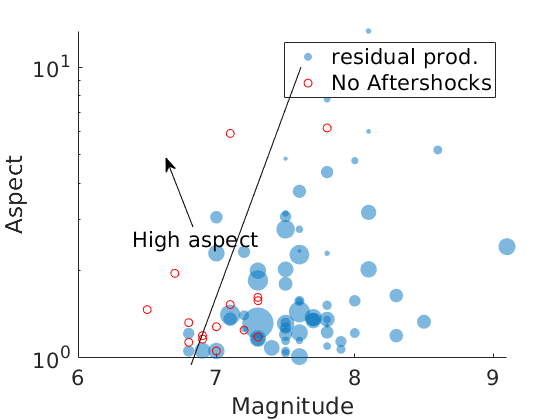

load analysis_catalog.mat
% Basic variables
% All variables are presented in SI units if not otherwise indicated

M                   = CAT.MSmag;
Mo                  = 10.^((M+10.7)*3/2)/10^7;
depth               = CAT.MSdepth*1000;
productivity        = CAT.MSprod;
residualProductivity= CAT.MSres;
MeBB                = CAT.MeBB_appended_cat1;
MeHF                = CAT.MeHF_appended_cat1;
meanSlip            = CAT.av_slip_appended_cat2;
faultWidth          = CAT.rwid_appended_cat2*1000;
faultLength         = CAT.rlen_appended_cat2*1000;
faultPerimeter      = CAT.Perimeter_appended_cat2;
stressDrop          = CAT.StressDrop_appended_cat2*10^6;
heterogeneity       = CAT.EllipseErrorNorm_appended_cat2;

% normalized/linearized parameters:

logSD               = log10(stressDrop);
MeBBNorm            = MeBB./M;
MeHFNorm            = MeHF./M;
depthNorm           = abs(depth-mean(depth))/mean(depth);
Ar                  = faultWidth./faultLength;
Ar(Ar<1)            = 1./Ar(Ar<1);
logAr               = Ar;
PNorm               = faultPerimeter./(2*pi*(Mo*7/16./stressDrop).^(1/3));
H                   = heterogeneity;

figure 
scatter(M(~isinf(residualProductivity)),Ar(~isinf(residualProductivity)), (10*(residualProductivity(~isinf(residualProductivity)) - min(residualProductivity(~isinf(residualProductivity))))).^2 + 10,'filled','MarkerFaceAlpha',0.5)
xlabel('Magnitude')
ylabel('Aspect')
set(gca,'YScale','log')
hold on 
scatter(M(isinf(residualProductivity)),Ar(isinf(residualProductivity)),'r')

annotation('line',[0.5375 0.3411],[0.8405 0.131])
annotation('textarrow',[0.3446 0.2964],[0.4595 0.6238],'String','High aspect')

legend({'residual prod.','No Aftershocks'})
set(findall(gcf,'-property','FontSize'),'FontSize',16)

Inverse problem 


% store variables into X
X = [logSD, MeBBNorm, MeHFNorm, depthNorm, logAr, PNorm, H];
Y = residualProductivity;
badI = any([isnan(X),isinf(X),isnan(Y),isinf(Y)],2);
X = X(~badI,:);
Y = Y(~badI);
SX= size(X);
X = X - repmat(mean(X,1),SX(1),1); % remove average value
Y = Y - mean(Y);

BETA = (X'*X)\X'*Y;
% comput2 R^2
R2         = 1  -  sum((X*BETA - Y).^2)/sum(Y.^2);
R2adjusted = 1  -  (SX(1)-1)/(SX(1)-SX(2)) * sum((X*BETA - Y).^2)/sum(Y.^2);
% remove outlier (rinse and repeat)

var = (X*BETA - Y).^2;
outlierInd = var > 4*mean(var);
X = X(~outlierInd,:);
Y = Y(~outlierInd);
SX= size(X);
X = X - repmat(mean(X,1),SX(1),1); % remove average value
Y = Y - mean(Y);
BETA = (X'*X)\X'*Y;

% comput2 R^2
R2         = 1  -  sum((X*BETA - Y).^2)/sum(Y.^2);
R2adjusted = 1  -  (SX(1)-1)/(SX(1)-SX(2)) * sum((X*BETA - Y).^2)/sum(Y.^2);
Xrand      = rand(SX(1),SX(2));
Yscaled    = Y./max(Y);
BETA = (Xrand'*Xrand)\Xrand'*Yscaled;
R2         = 1  -  sum((Xrand*BETA - Yscaled).^2)/sum(Yscaled.^2);
R2adjusted = 1  -  (SX(1)-1)/(SX(1)-SX(2)) * sum((Xrand*BETA - Yscaled).^2)/sum(Yscaled.^2);

R       = zeros(1,SX(2));
Rrand   = R;

for n = 1:SX(2)
    Xcol    = X(:,n);
    BETA    = (Xcol'*Xcol)\Xcol'*Y;
    R(n)    = 1  -  sum((Xcol*BETA - Y).^2)/sum(Y.^2);  
end
maxR = max(R);

mIt = 10000;
maxRandom = zeros(mIt,1);
for m = 1:mIt
    for n = 1:SX(2)
        Xrand   = rand(SX(1),1);
        BETArand= (Xrand'*Xrand)\Xrand'*Yscaled;
        Rrand(n)= 1  -  sum((Xrand*BETArand - Yscaled).^2)/sum(Yscaled.^2);
    end
    maxRandom(m) = max(Rrand);
end

SourceParameters = {'logSD', 'MeBBNorm', 'MeHFNorm', 'depthNorm', 'Ar', 'PNorm', 'H'};
Rvalues = table(SourceParameters',R')

Rvalues = 7×2 table
       Var1           Var2   
    ___________    __________

    'logSD'         0.0033013
    'MeBBNorm'      0.0077981
    'MeHFNorm'       0.022488
    'depthNorm'    0.00033756
    'Ar'              0.17943
    'PNorm'        2.2488e-05
    'H'              0.058144


Start of plots

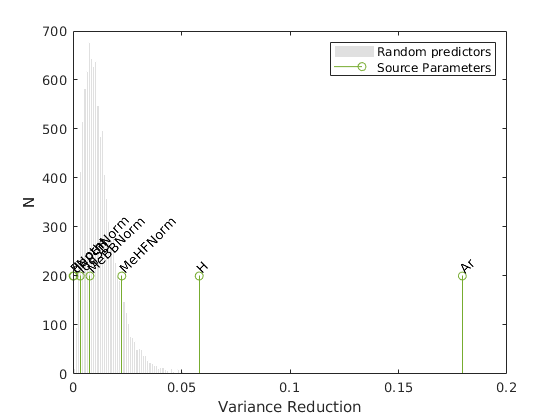


figure 

Hhist = histogram(maxRandom,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1]);
hold on
stem(R,2*sqrt(mIt)*ones(length(R), 1))
texth = text(R, 2.1*sqrt(mIt)*ones(length(R),1), SourceParameters);
set(texth, 'Rotation', 45)
xlabel('Variance Reduction')
ylabel('N')
set(gca,'Xlim',[0,0.2])
legend({'Random predictors', 'Source Parameters'},'Location','northeast')

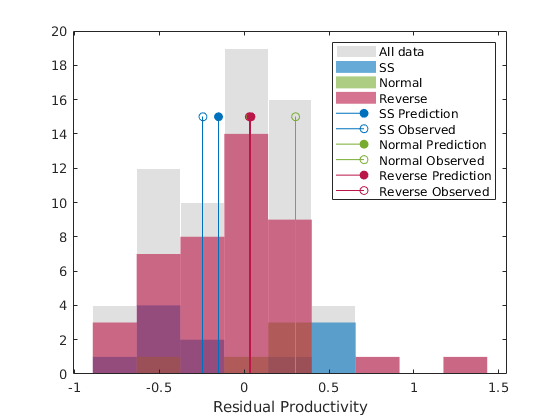


colChoice = [5,7];

figure
resRange    = minmax(residualProductivity(~isnan(residualProductivity') & ~isinf(residualProductivity'))');
binEdges    = linspace(resRange(1),resRange(2),10);
histogram(residualProductivity,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
fms         = fms(~badI);
fms         = fms(~outlierInd);

hold on
C = {'b','g','r'};
Xfms = zeros(3,length(colChoice));
for n =1:3
    I = fms == n;
    histogram(residualProductivity(I),binEdges,'FaceColor',colors{n},'EdgeColor','none')
    Xfms(n,:) = mean(X(I,colChoice),1);
end

% inverse problem
Xgood = X(:,colChoice);
BETAgood = (Xgood'*Xgood)\Xgood'*Y;
% forward prediction:
Yprediction = Xfms*BETAgood;

for n = 1:3
    stemH1 = stem(Yprediction(n),15,'filled');
    stemH1.Color = colors{n};
    stemH2 = stem(mean(Y(fms == n)), 15);
    stemH2.Color = colors{n};
end

legend({'All data','SS','Normal','Reverse', ...
    'SS Prediction','SS Observed', ...
    'Normal Prediction','Normal Observed', ...
    'Reverse Prediction', 'Reverse Observed'})
xlabel('Residual Productivity')

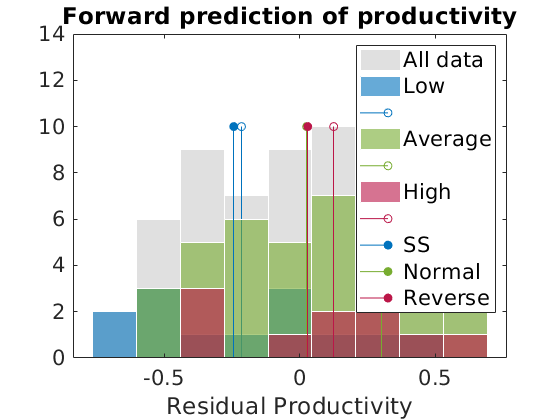


figure
resRange    = minmax(Y');
binEdges    = linspace(resRange(1),resRange(2),10);
histogram(Y,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
YpredAll = Xgood*BETAgood;
pctRange = prctile(YpredAll,[0,20,80,100]);
for n = 1:3
    Ipct = YpredAll >= pctRange(n) & YpredAll < pctRange(n+1);
    histogram(Y(Ipct), binEdges, 'FaceColor',colors{n},'EdgeColor',[1 1 1])
    S = stem(mean(Y(Ipct)), 10);
    S.Color = colors{n};
end
for n = 1:3
    S = stem(mean(Y(fms == n)), 10,'filled');
    S.Color = colors{n};
end
legend({'All data','Low','','Average','','High','','SS','Normal','Reverse'})
title('Forward prediction of productivity')
xlabel('Residual Productivity')
set(findall(gcf,'-property','FontSize'),'FontSize',16)

As a seprate test we can also see whether these parameters are also good at seperating the data in the population of another focal mechanism.

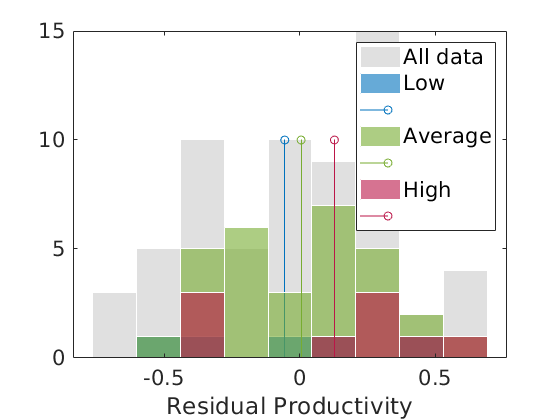

figure
histogram(residualProductivity,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
I = fms == 3 ;
for n = 1:3
    Ipct = YpredAll >= pctRange(n) & ...
        YpredAll < pctRange(n+1) & ...
        I;
    
    histogram(Y(Ipct), binEdges, 'FaceColor',colors{n},'EdgeColor',[1 1 1])
    S = stem(mean(Y(Ipct)), 10);
    S.Color = colors{n};
end
legend({'All data','Low','','Average','','High',''})
xlabel('Residual Productivity')
set(findall(gcf,'-property','FontSize'),'FontSize',16)


load handel
sound(y,Fs)

The above formalism provide an objective basis  to understand why strike slip earthquakes may be deficient in aftershocks.

function bootstrapHist()
colors              = {[0         0.4470    0.7410]; ...
                       [0.4660    0.6740    0.1880]; ...
                       [0.7350    0.0880    0.2840]}; % set this
load mainshock_info.mat

figure
Mcutoff = 7;
nbtstrp = 100000;
I           = ~isinf(MSres) & ...
    MSmag > Mcutoff;
MSresNoInf = MSres(I);
MSfmsNoInf = MSfms(I);
nEqNoInf   = length(MSresNoInf);

hold on

for n = 1:3
    Ipct = MSfmsNoInf == n;
    numI = sum(Ipct);
    [res] = bootstrp(floor(nbtstrp*numI/nEqNoInf),@mean, MSresNoInf(Ipct));
    histogram(res,'BinWidth',0.01, 'FaceColor',colors{n},'EdgeColor','none')
end
title(sprintf('Bootstrap (n = %d) for M%d+ Mainshocks', nbtstrp, Mcutoff))
xlabel('Residual Productivity')
set(gca,'Ytick',[])
set(findall(gcf,'-property','FontSize'),'FontSize',9)
end